# SOLUTION OF EXAMPLE EXERCISES

## EX1 - 2 masses connected by springs

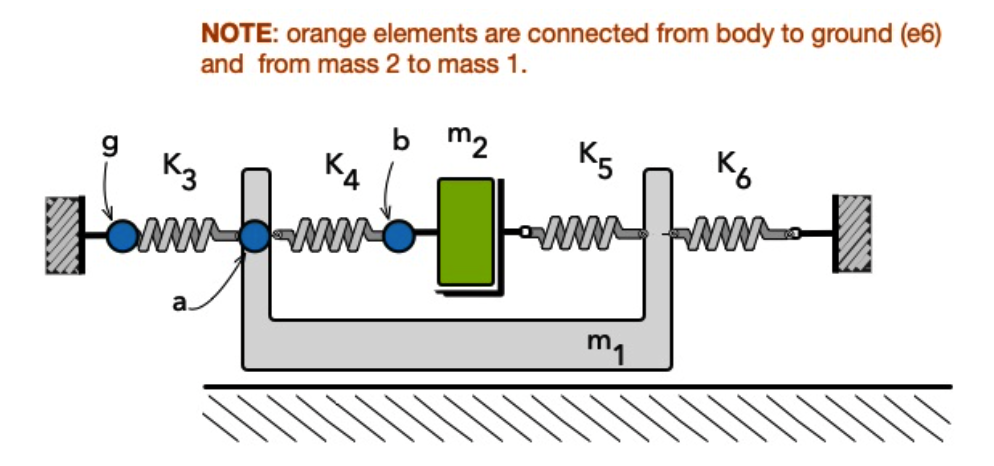

Equivalent system representation:

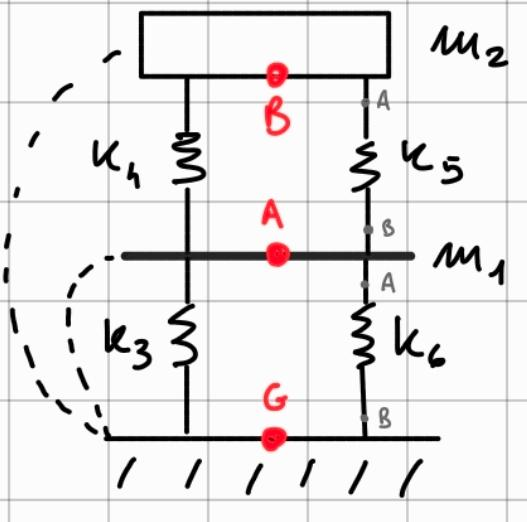

Linear Graph:

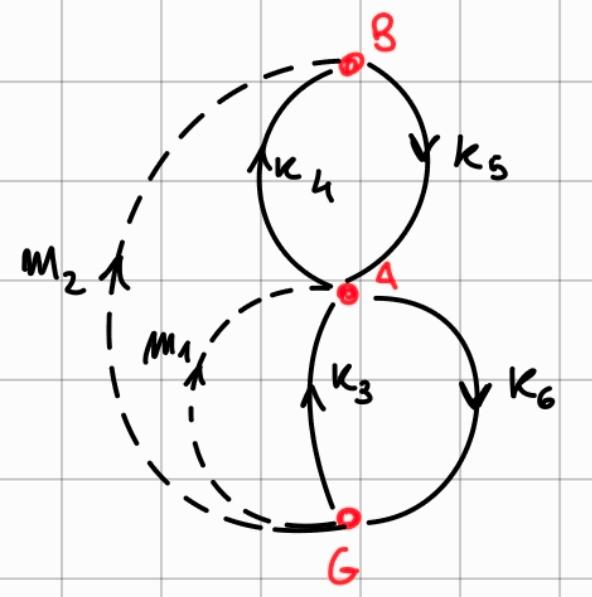

**Elements:**

- 4 mechanical springs (T-Type) --> 4 edges

- 2 masses (A-Type) --> 2 edges

### Definitions

clear; clc; close all;
addpath('MBsLib_v2')

% Define the system variables (through and across for each element)
syms t

N = 6; % Num of edges

% Through variables
syms v_m1(t) v_m2(t) x_k3(t) x_k4(t) x_k5(t) x_k6(t)
%                em1     em2     ek3     ek4     ek5     ek6
tau_vars =      [v_m1(t) v_m2(t) x_k3(t) x_k4(t) x_k5(t) x_k6(t)].';

% Across variables
syms F_m1(t) F_m2(t) F_k3(t) F_k4(t) F_k5(t) F_k6(t)
%                em1     em2     ek3     ek4     ek5     ek6
alpha_vars =    [F_m1(t) F_m2(t) F_k3(t) F_k4(t) F_k5(t) F_k6(t)].';

% CHECK: length of arrays is the same

### Constitutive equations

for each element (edge of the LG)

% Const. equations vector
% N.B. DIFFERENTIAL FIRST, algebraic later

syms m1 m2 k3 k4 k5 k6 % physical (constant) parameters

eqns_const = [
    % mass m1
    diff(v_m1,t) == 1/m1*F_m1(t);  % d/dt(v_m1) = F_m1(t)/m1
    % mass m2
    diff(v_m2,t) == 1/m2*F_m2(t);
    % spring k3
    F_k3(t) == k3*x_k3(t);
    % spring k4
    F_k4(t) == k4*x_k4(t);
    % spring k5
    F_k5(t) == k5*x_k5(t);
    % spring k6
    F_k6(t) == k6*x_k6(t)
    ]

size(eqns_const)

### Loop and node equations

#### Incidence matrix

% Write it directly without singular rows (e.g. LIN DEP)
IM = [
    1 0 1 -1 1 -1;...
    0 1 0 1 -1 0;...
    1 1 1 0 0 -1
]

% Number of nodes and edges
[nn, ne] = size(IM);

rref(IM)
% Number of nonsingular rows
nnsr = nn - rank(IM);

% Number of elements, branches, chords
nb = nn-nnsr;
nc = ne - nb;

A matrix

% A matrix
A = sym(IM(1:nb, 1:ne))
% Af and Ac as Af = [Ib | Ac]
Af = rref(A)

Ac = Af(:, nb+1:end)

B matrix

Bf = null(Af).'

% CHECK: Af*Bf' --> all zeros matrix

Bb = -Ac'

#### Node equations (Newton @ nodes)

node_eqns = tau_vars(1:nb) == -Ac * tau_vars(nb+1:ne)

#### Circuit/Loop equations

loop_eqns = alpha_vars(nb+1:ne) == -Bb * alpha_vars(1:nb)

### DAE system of equations

#### Dependent and independent coordinates

% DEPENDENT --> set of Chord Across coords and Through Branch coords
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

% INDEPENDENT --> rest of the vars
allvars = [alpha_vars; tau_vars];
dae_vars = setdiff(allvars, qvars_d)

#### Assembling and solving equations

% Subs loop equations into constitutive equations
tmp = subs(eqns_const, lhs(loop_eqns), rhs(loop_eqns));
% Then subs node equations into constitutive equations
dae_eqns = subs(tmp, lhs(node_eqns), rhs(node_eqns))

% CHECKS:
~(length(qvars_d)==N)
% ~(length(eqns_const)==N)
% ~(length(dae_eqns)==length(dae_vars))

#### Equations manipulation: index reduction

[E_mat, G_mat] = massMatrixForm(dae_eqns, dae_vars)

Dulmage-Mendelsohn to reorder equations

[p,q,~,~,~,~] = dmperm(double(E_mat));  % Only need p and q aka row and col permutation vectors
                                        % such that E_mat is in block diagonal form
E_sorted = E_mat(p, :) % Only change equation order
G_sorted = G_mat(p)

% Number of differential equations in the system = rank(E_sorted)
n_ode = rank(E_sorted)

Sorted set of equations

eqns_sorted = E_sorted * diff(dae_vars,t) == G_sorted

ODE equations and variables

% Extract ODEs
ode_eqns = eqns_sorted(1:n_ode)
% Extract ODE variables
ode_vars = get_ode_vars(dae_vars, ode_eqns)

Algebraic equations and variables

% Extract alg eqns
alg_eqns = eqns_sorted(n_ode+1:end)
% Extract alg vars
alg_vars = setdiff(dae_vars, ode_vars)

### Index reduction procedure

Necessary if algebraic equation at this step ....... ????? WTH IS DAE INDEX

% First differentiation:
d_alg_eqns1 = diff(alg_eqns,t);
% 
% assemble system
dae_eqns1 = [ode_eqns;d_alg_eqns1]
% Compute the E matrix and G vector for new system
[E_mat1,G_vec1] = massMatrixForm(dae_eqns1,dae_vars);

% Compute LU
[L1,U1,P1] = lu(E_mat1);
L1;
U1;
% Check the rank of the system: is full
% the system is index 1
n_ode1 =  rank(U1)
length(dae_vars)==n_ode1
% The system reduced to pure ode
% Since we made one differentiation the system is index dae 1
eqns_ode_reduced =  diff(dae_vars,t)==U1\L1\(P1*G_vec1)
% The list of invariants is
invariants = [alg_eqns];

### Numerical solution

Solve the algebraic equations

syms y [length(alg_vars),1]
tmp = subs(alg_eqns, alg_vars, y);
sol_alg = solve(tmp, y)

Final system of ODEs to solve

reduced_ode = subs(subs(ode_eqns, alg_vars, y), sol_alg)

Numerical data

% Given system data
data.m1 = 10; % kg
data.m2 = 20; % kg
data.k3 = 1000;
data.k4 = 500;
data.k5 = 450;
data.k6 = 2000;

ode_red = subs(reduced_ode, data)

Incomprehensible after this point...

## EX2 - Solved multidomain exercise

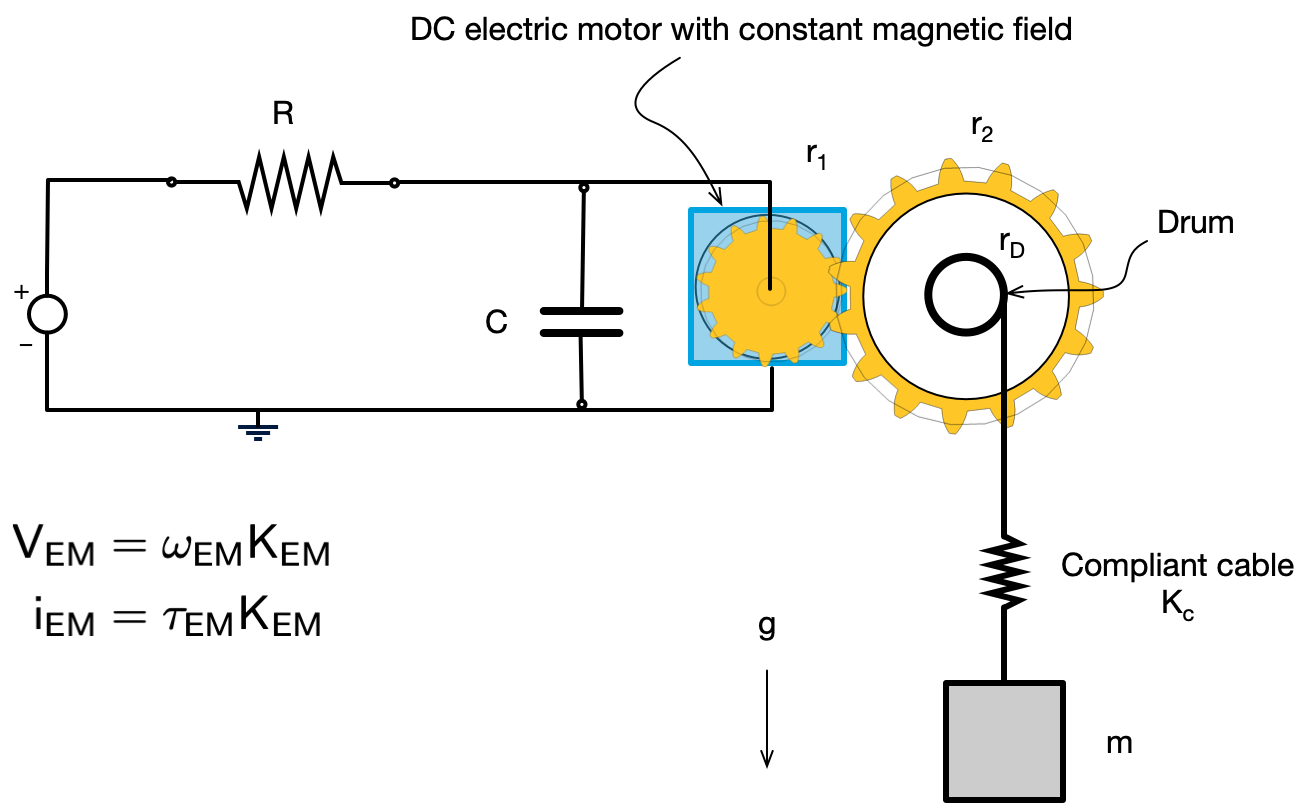

Linear Graph:

**N.B. ****Drum**** () is a ****mechanical transformer**

### Definitions

clear;
clc;
close all;
addpath('MBLibs/');

syms t;

N = 11; % Number of edges

% Across variables definition
syms V_s(t) V_R(t) V_C(t) V_em(t); % electrical side
syms w_em(t) w_gA(t) w_gB(t) w_dA(t) v_dB(t) v_k(t) v_m(t); % mechanical domain
            %   e1      e2    e3     e4     e5      e6      e7      e8     e9      e10     e11
alpha_vars  = [V_s(t) V_C(t) v_m(t) w_em(t) w_gB(t) v_dB(t) V_R(t) v_k(t) w_dA(t) w_gA(t) V_em(t)].'
% Through var def
syms i_s(t) i_R(t) i_C(t) i_em(t); % Electrical side
syms T_em(t) T_gA(t) T_gB(t) T_dA(t) F_dB(t) F_k(t) F_m(t); % Mechanical domain
            %   e1      e2    e3     e4     e5      e6      e7      e8     e9      e10     e11
tau_vars    = [i_s(t) i_C(t) F_m(t) T_em(t) T_gB(t) F_dB(t) i_R(t) F_k(t) T_dA(t) T_gA(t) i_em(t)].'

### Constitutive equations

syms V_0 R C K_em r1 r2 r tau g m K_c
tau = r1/r2 % gear ratio of gear train

eqns_const = [
    % Voltage source
    V_s == V_0;
    % Capacitor
    diff(V_C,t) == 1/C * i_C;
    % Mass (with added negative gravitational contribution
    diff(v_m,t) == 1/m * F_m - m*g;
    % Electric Motor (2 eqs)
    V_em == 1/K_em * w_em;  % a1 = 1/n * a2
    i_em == -K_em * T_em;   % t1 = -n * t2
    % Gear train (2 eqs)
    w_gA == 1/tau * w_gB;
    T_gA == -tau * T_gB;
    % Drum (2 eqs) --> Transforms torque and angular vel into force and linear vel
    w_dA == 1/r * v_dB;
    T_dA == -r * F_dB;
    % Resistor
    V_R == R * i_R;
    % Spring
    diff(F_k,t) == K_c * v_k;
]

### Incidence Matrix

IM = [
%   e1  e2  e3  e4  e5  e6  e7  e8  e9  e10 e11
    1   0   0   0   0   0   -1  0   0   0   0   ;... N1
    0   1   0   0   0   0   1   0   0   0   1   ;... N2
    0   0   0   1   0   0   0   0   0   1   0   ;... N3
    0   0   0   0   1   0   0   0   1   0   0   ;... N4
    0   0   0   0   0   1   0   -1  0   0   0   ;... N5
    0   0   1   0   0   0   0   1   0   0   0   ;... N6
    -1  -1  0   0   0   0   0   0   0   0   -1  ;... Ge
    0   0   -1  -1  -1  -1  0   0  -1   -1  0   %   Gm
]

[nn, ne] = size(IM);
% CHECK: all the columns of IM have to sum to 0
sum_rows = 0;
for i=1:ne
    for j=1:nn
        sum_rows = sum_rows + IM(j,i);
    end
end
if ~(sum_rows==0)
    disp("Rows don't sum to 0, check the IM!!");
end

% Row reduced echelon form
rref(IM)

nnsr = rank(IM)

% Dimensions
nb = nnsr; % #branches
nc = ne - nb;   % #chords

**A matrix**

A = sym(IM(1:nb, 1:ne))
Af = rref(A)
Ac = Af(:, nb+1:end)
% CHECK
Ib = Af(:, 1:nb)

**B matrix**

Bf = null(Af).'
% CHECK
Af*Bf.'
Bb = -Ac'

### Loop and node equations

Node

node_eqns = tau_vars(1:nb) == -Ac * tau_vars(nb+1:ne)

Loop

loop_eqns = alpha_vars(nb+1:ne) == -Bb * alpha_vars(1:nb)

### DAE system of equations

% Dependent vars
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]
% Indep set of DAE vars
allvars = [alpha_vars; tau_vars];
dae_vars = setdiff(allvars, qvars_d)

#### Assembling equations

tmp = subs(eqns_const, lhs(loop_eqns), rhs(loop_eqns));
dae_eqns = subs(tmp, lhs(node_eqns), rhs(node_eqns))

### EQs manipulation: index reducion

Mass matrix form

[E_mat, G_vec] = massMatrixForm(dae_eqns,dae_vars)

Sorted E_mat and G_vec via dmperm

[p,q, ~,~,~,~] = dmperm(double(E_mat));
E_sorted = E_mat(p, :)
G_sorted = G_vec(p)

Sorted system of DAE

n_ode = rank(E_sorted)

dae_vars_sorted = flip(dae_vars(q))

eqns_sorted = E_sorted*diff(dae_vars_sorted,t)==G_sorted

Extract the first n_ode equations

ode_eqns = eqns_sorted(1:n_ode)

Vector of differential variables

ode_vars = get_ode_vars(dae_vars, ode_eqns)

Vector of algebraic variables

alg_vars = setdiff(dae_vars, ode_vars)

Algebraic equations

alg_eqns = eqns_sorted(n_ode+1:end)

### Numerical solution

System is index-1 so we can try to solve the linear algebraic equations and subs tthe solutions into the DAEs

syms y [length(alg_vars),1]
tmp = subs(alg_eqns, alg_vars, y)
sol_alg = solve(tmp, y, 'ReturnConditions', true)

## EX3 - Exam 22/06/2026

### Definitions

clear;
clc;
close all;

addpath('MBLibs')

syms t;

% N = 9; % number of edges

% Through variables
syms F_mL(t) F_mW(t) Q_c(t) F_cL(t) F_cW(t) F_ks(t) Q_R(t) F_p(t) F_L(t)
% Across vars
syms v_mL(t) v_mW(t) P_c(t) v_cL(t) v_cW(t) v_ks(t) P_R(t) v_p(t) v_L(t)

%            e1      e2      e3      e4      e5      e6      e7      e8      e9
tau_vars =  [F_mL(t) F_mW(t) Q_c(t) F_cL(t) F_cW(t) F_ks(t) Q_R(t) F_p(t) F_L(t)].'
%            e1      e2      e3      e4      e5      e6      e7      e8      e9
alpha_vars= [v_mL(t) v_mW(t) P_c(t) v_cL(t) v_cW(t) v_ks(t) P_R(t) v_p(t) v_L(t)].'

### Constitutive equations

syms mL mW A_c cL cW ks R F_0

eqns_const = [
    % Mass mL
    diff(v_mL,t) == 1/mL * F_mL;
    % Mass mW
    diff(v_mW,t) == 1/mW * F_mW;
    % Coupler
    Q_c == A_c * v_p;
    F_p == A_c * P_c;
    % Rolling friction model: Dampers cL and cW
    F_cL == cL * v_cL;
    F_cW == cW * v_cW;
    % Spring
    diff(F_ks,t) == ks * v_ks;
    % Fluid resistor
    P_R == R * Q_R;
    % Force source
    F_L == F_0
]

### Incidence matrix

IM = [
%   e1  e2  e3  e4  e5  e6  e7  e8  e9    
    1   0   0   1   0   1  0   -1  1   ;... % N1
    0   1   0   0   1   -1   0   1   0   ;... % N2
    0   0   -1  0   0   0   -1  0   0   ;... % N3
    0   0   1   0   0   0   1   0   0   ;... % N4
    -1  -1  0   -1  -1  0   0   0   -1       % G
]

[nn, ne] = size(IM);

rref(IM)

nnsr = rank(IM)

% Branches
nb = nnsr
% Chords
nc = ne - nb

A matrix

A = sym(IM(1:nb, 1:ne))

Af = rref(A)

Ac = Af(:, nb+1:end)

B matrix

Bf = null(Af).'
Bb = -Ac'

#### Node and loop equations

node_eqns = tau_vars(1:nb) == -Ac * tau_vars(nb+1:end)
loop_eqns = alpha_vars(nb+1:end) == -Bb * alpha_vars(1:nb)

### DAE system of equations

% Dependent variables
qvars_d = [lhs(node_eqns); lhs(loop_eqns)]

% Independent vars
allvars = [alpha_vars; tau_vars];
dae_vars = setdiff(allvars, qvars_d)

### Assembling and solving equations

tmp = subs(eqns_const, lhs(node_eqns), rhs(node_eqns));
dae_eqns = subs(tmp, lhs(loop_eqns), rhs(loop_eqns))

### Index reduction

[E_mat, G_vec] = massMatrixForm(dae_eqns, dae_vars)

Reordering the equations using DM permutation

[p,q,~,~,~,~] = dmperm(double(E_mat));
E_sorted = E_mat(p, :)
G_sorted = G_vec(p);

eqns_sorted = E_sorted*diff(dae_vars) == G_sorted

Extracting ODE eqns

n_ode = rank(E_sorted)
ode_eqns = eqns_sorted(1:n_ode)
ode_vars = get_ode_vars(dae_vars, ode_eqns)

Extracting algebraic equations

alg_vars = setdiff(dae_vars, ode_vars)
alg_eqns = eqns_sorted(n_ode+1:end)

### Solution

syms y [length(alg_vars),1]
tmp = subs(alg_eqns, alg_vars, y)
alg_sol = solve(tmp, y)

Reduced ODE system:

reduced_ode = subs( subs(ode_eqns, alg_vars, y), alg_sol)

#### Data

% system data
data.mL  = 80e3; % kg
data.mW  = 50e3; % kg
data.ks = 1.5e6; % N/m
data.cL = 1.0e3; % Ns/m
data.cW = 0.8e3; % Ns/m
data.A_c  = 7.85e-3; % m^2
data.beta = 1.4e9; % bulk modulus  (Pa)
data.V_0  = 2*3.0e-3; % m^3
data.R    = -4e8; % Orifice discharge coefficient
%data.V0 = 24;
locomotive_thrust = -250e3*sin(atan(1*t));

% substitute data
ode_red = subs(subs(reduced_ode,data), F_0, locomotive_thrust)

#### Initial Conditions

[MM,FF] = massMatrixForm(ode_red, ode_vars);
ode_rhs = odeFunction(FF, ode_vars)

% Initial conditions on ODE vars
ics = [
    0.0;    % F_ks(0)
    0.0;    % v_mL(0)
    0.0     % v_mW(0)
]

tspan = [0, 5]; % simulation time span

Call Runge Kutta 45 solver

[tS, yS] = ode45(@(t,x)ode_rhs(t,x), tspan, ics);

Plots

% Plot the results
figure;
tiledlayout(3,1)
nexttile
plot(tS, yS(:,2),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('Locomotive speed');

nexttile
plot(tS, yS(:,3),'LineWidth',2);
xlabel('Time (s)');
ylabel('[m/s]');
title('Wagon speed');

nexttile
plot(tS, yS(:,1),'LineWidth',2);
xlabel('Time (s)');
ylabel('[N]');
title('Coupler spring force');

grid on;